# MATLAB Instruction - Farfield evaluation using SGF

# **Farfield evaluated using SGF**

## **Theory**

The electric field radiated by an electric current can be expressed as follows:

when considering stationary phase point, the farfield can be evaluated asmptotically:

where $\left(x^{\prime } ,y^{\prime } ,z^{\prime } \right)$is the source position while $\left(x,y,z\right)$ is the observation position, $k_{\mathrm{xs}} =k\sin \theta \cos \phi ,k_{\mathrm{ys}} =k\sin \theta \sin \phi ,k_{\mathrm{zs}} =k\cos \theta \;$rerepresent the dominant plane wave,$\overrightarrow{J} \left(k_x ,k_y \right)$ is the FT of the current distribution, and ${\tilde{G} }^{\textrm{ej}}$ is the dyadic SGF for electric currents 


$${\bar{\bar{G} } }^{{\;}^{ej} } \left(k_x ,k_y \right)=-\frac{\zeta \;}{2{kk}_z }\left\lbrack \begin{array}{ccc}
k^2 -k_x^2  & -k_x k_y  & -k_x \left(\pm k_z \right)\\
-k_x k_y  & k^2 -k_y^2  & -k_y \left(\pm k_z \right)\\
-k_x \left(\pm k_z \right) & -k_y \left(\pm k_z \right) & k^2 -k_z^2 
\end{array}\right\rbrack$$


**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

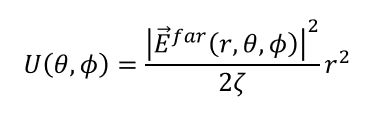

and $P_{\textrm{rad}}$ is the total radiated power:

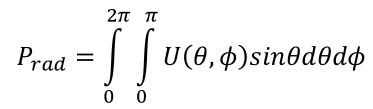

## MATLAB Implementation

To evaluate the farfield radiated by a current, we should perform the following steps:

**(1)** Calculate the dyadic SGF. **(2)** Obtain the FT of the current distribution. **(3)** Use Eq.2 to evaluate the farfield. **(4) **Estimate the directivity of the farfield.

The above steps are applicable for any source so it would be convenient to build separate routines for these steps, and then reuse it for different applications. Today you should learn how to build the routines:

**(1)**  ej_SGF = **EJ_SGF**(er, k, kx, ky)

**(2)** Jx = **FTCurrent**(k, er, kx, ky, l, w)

**(3)** [Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx)

**(4)** [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

# Q1 (3 points): Elementary electric source

Write a Matlab routine to calculate the free space *Spectral Green’s Function* (SGF) of an elementary electric source oriented along $\hat{x}$ and placed at the origin of the reference system.

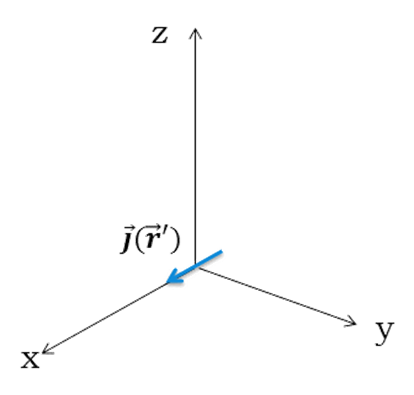

### 1. Plot the x-, y-, and z-components of the SGF, given the $\hat{x}$-oriented current. 

Both real and imaginary parts should be plotted. Consider$f=30$ GHz, $k_x \in \left\lbrack 0,3k_0 \right\rbrack$ and $k_y =0$. 

**Routines to calculate SGF**

It would be conveninent to write a routine to calculate the complete SGF for electric currents: [ej_SGF] = **EJ_SGF**(er, k, kx, ky)


$${\bar{\bar{G} } }^{{\;}^{\textrm{ej}} } \left(k_x ,k_y \right)=-\frac{\zeta \;}{2{\textrm{kk}}_z }\left\lbrack \begin{array}{ccc}
k^2 -k_x^2  & -k_x k_y  & -k_x \left(\pm k_z \right)\\
-k_x k_y  & k^2 -k_y^2  & -k_y \left(\pm k_z \right)\\
-k_x \left(\pm k_z \right) & -k_y \left(\pm k_z \right) & k^2 -k_z^2 
\end{array}\right\rbrack$$


Note that $k_z$ should be defined uniquely as follows:

**Elementary source in free space**

In this case,$\overrightarrow{j} \left(x,y,z\right)=\delta \left(x\right)\delta \left(y\right)\delta \left(z\right)\hat{x}$, and its FT is $\overrightarrow{J} \left(k_x ,k_y \right)=\hat{x}$.

### **2. In which region of the spectrum is the x-component imaginary? Justify your answer with the plot and the SGF expression.**

# Q2 (4 points): Farfield of a dipole

Write a Matlab program to calculate the far field radiated in the upper hemisphere by the  dipole shown in the figure using the free space SGF. 

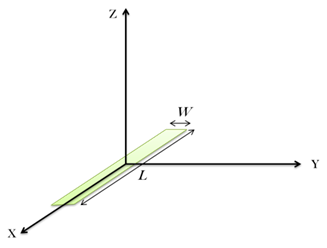

### 1. 1D plot of the farfield in main planes

Consider a dipole: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz, and calculate the far field (total field) for $\phi =0^{\circ \;} /{{45}^{\circ \;} /90}^{\circ \;}$.

**Farfield evaluated using SGF**

**Step 1:  Calculate the dyadic SGF**

Build the dyad for electric current: [ej_SGF] = **EJ_SGF**(er, k, kx, ky)

**Step 2:  Calculate the FT of the current distribution**

For dipole antennas, we can approximate the spatial current distribution using the current distribution along an open circuited transmission line. This distribution can be expressed in general as follows:

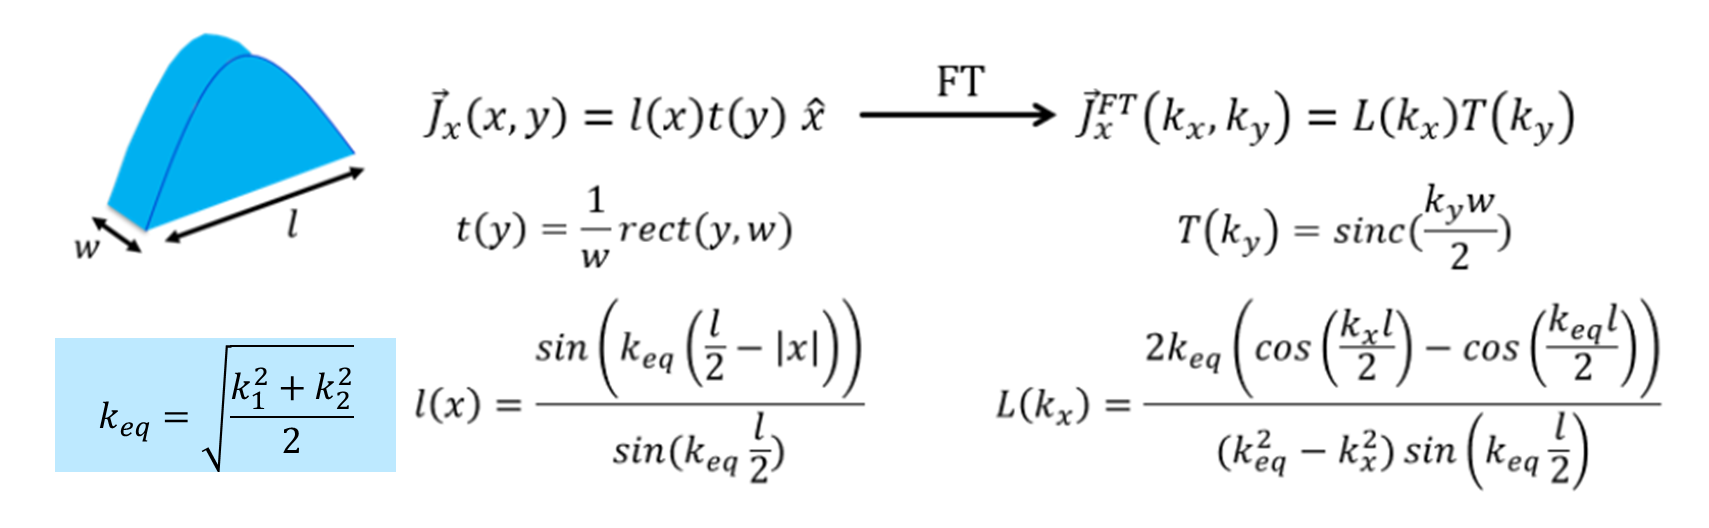

Write a routine to calculate the FT of currents: Jx = **FTCurrent**(k0, er, kx, ky, l, w)

**Step 3:  Evaluate the farfield (total field)** 

Calculate the FF in Eth and Eph and plot the total field: 

[Eth, Eph] = **farfield**(k0, R_FF, TH, PH, Gxx, Gyx, Gzx, Jx, kz, z)

%[Eth, Eph] = farfield(k0, R_FF, TH, PH, KZ, Gxx, Gyx, Gzx, Jx)

### 2. Farfield in the upper medium (z>0) plotted using UV representation.

In UV plane: $U=\sin \theta \;\cos \phi ,V=\sin \theta \;\sin \phi$.

Please use a representation such as 'surface' (with a top view), 'pcolor', or 'imagesc', and use a dynamic range of 10 dB

### 3. Evaluated the directivity at broadside in dB as a funciton of frequency 

Calculate the FF as a function of frequency and evaluate the directivity for each frequency. The dipole dimensions are: $L=5$ mm, $W=0\ldotp 25$mm.

**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

and $P_{\textrm{rad}}$ is the total radiated power:

We can build a routine to calculate the directivity: [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

# Q3 (3 points): Dipole with a backing reflector

Consider a dipole: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz, that is radiating in the presence of an infinite PEC plane as shown in the figure.

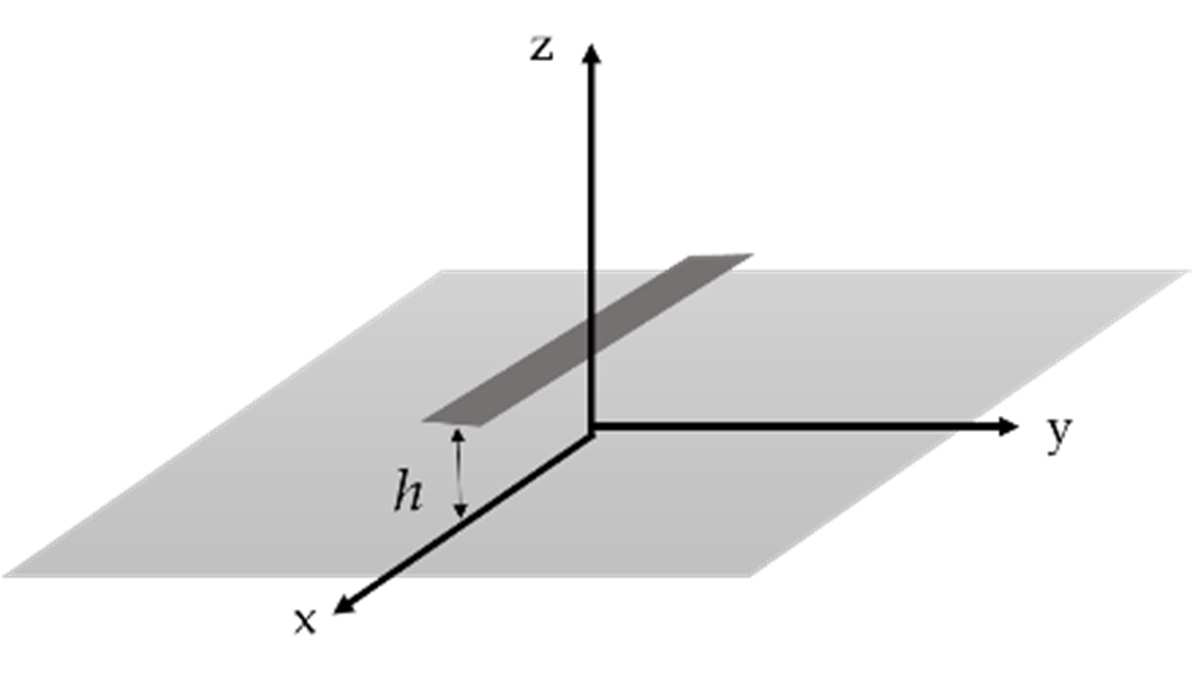

### 1. Plot 1D the farfield along the main planes and compare it to the one in Q2.

Here we consider $h=7\ldotp 5$ mm. To remove the PEC plane and use free space's GF, we can resort to image theorem. 

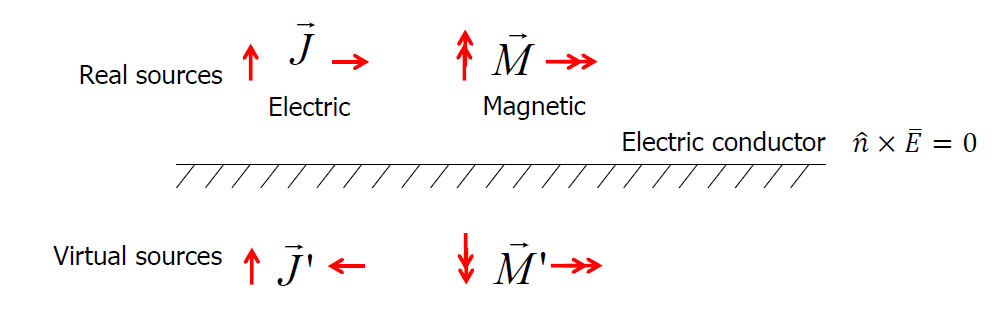

Before assessing the farfield numerically, please write down the analytical expression of the current spectrum.

**Step 1:  Calculate the dyadic SGF**

**Step 2:  Calculate the FT of the current distribution**

**Step 3:  Evaluate the far field (total field)**

### 3. Evaluate the directivity at broadside (linear scale) as a function of the distance $\mathit{\mathbf{h}}$ from the ground plane 

Plot the result from $h=\lambda_0 /10$ to $h={2\lambda }_0$. Please express the x-axis in terms of the wavelength.

In which domain do you integrate to calculate the radiated power? (**Hint: you have applied the image theorem...**)

Consider the spectrum calculated in Q3.1. For which values of $h$ do you expect a null at broadside (please think about the correct expression of $k_z$)? 

What is the power radiated for $h=0$? Please use the spectrum and/or the image. Verify it numerically.  

**Note: Please explain all the figures and results!**